# **Práctica 4: Convolución y Correlación de señales en tiempo continuo**

## **Problema 1**

clear all; clc; close all;

Las Señales del PR04, 1 problema son:

$\[ x(t) = \begin{cases} 
      -t + 1 & 0\leq t \lt 1 \\
      t-1 & 1\lt x\leq 2 \\
      0 & otro \ caso 
   \end{cases}
\]$  y $\[f(t) = \begin{cases}
 1 & 0 \leq t \leq 1 \\
 0 & otro \ caso
 \end{cases}
\]$ 

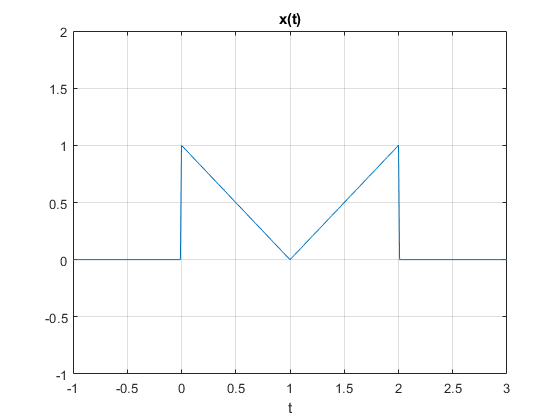

x = @(t) (-t+1).*((t >= 0) & (t<1)) + (t-1).*((1 < t)&(t <= 2));
xV = (-1: 0.01: 4);
plot(xV, x(xV));
axis([-1 3 -1 2]);
title('x(t)');
xlabel('t');
grid on;

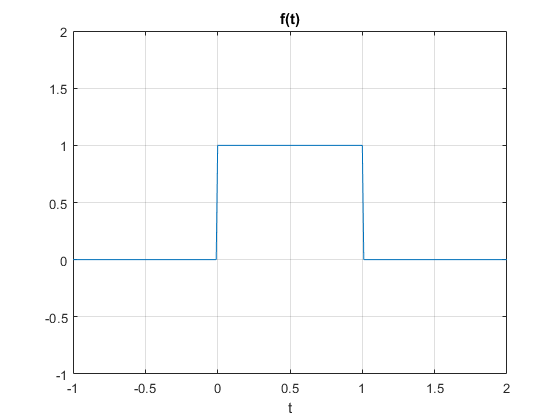

f = @(t) (1.*((0 <= t)&(t <= 1)));
fV = (-1: 0.01: 2);

plot(fV, f(fV));
axis([-1 2 -1 2]);
title('f(t)');
xlabel('t');
grid on;

Para aplicar la convolución, usaríamos la definición y nuestra señal inversa movible  va a ser f(t):

$h(x) = x(t)*f(t)= \int_{-\infty}^{\infty}x(\tau)f(t-\tau)\, d\tau$}

La convolucíon resultante sería:


$$\[ h(t) = 
\begin{cases}
-\frac{t^2}{2}+ t & 0 \lt t \leq 1 \\
t^2-3t+\frac{5}{2} &1 \lt t \leq2 \\ 
-\frac{t^2}{2}+ 2t - \frac{3}{2} & 2 \lt t \le 3 \\
0 & otro\ caso
\end{cases}
\]$$


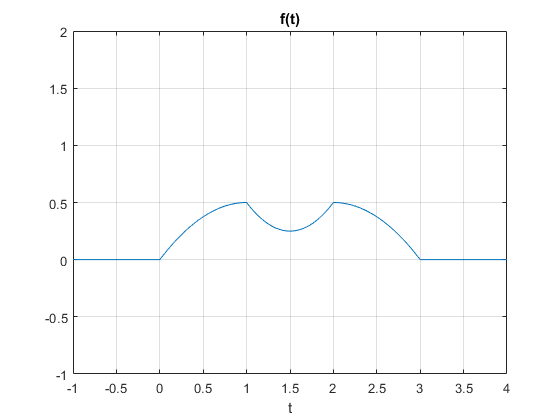

h = @(t) (-(t.^2)/2 + t).*((0 < t)&(t<=1)) + (t.^2-3*t+5/2).*((1 < t)&(t<=2))+ (-(t.^2)/2 + 2*t - 3/2).*((2 < t)&(t <= 3));
hV = (-1:0.01: 4);
plot(hV, h(hV));
axis([-1 4 -1 2]);
title('f(t)');
xlabel('t');
grid on;

Comparando la señal de la numérica generada con su resultado analítico, podemos observar que concuerda correctamente, esto se puede visualizar bien debido a que son intervalos muy pequeños los que se estan uniendo con rectas.

Esta sería el ejemplo gráfico de como se generaría la convolución.

z =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [404 247 560 420]
       Units: 'pixels'

  Show all properties


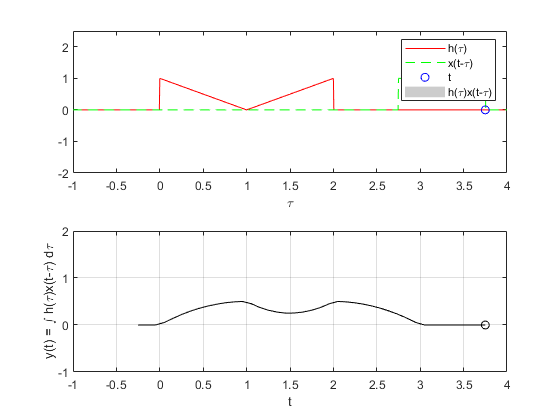

convconm(f,x, 'Problema1.gif');

## **Problema 3**

clear all; clc; close all;

Las Señales del PR04, 3er problema son:

$\[ y(t) = \begin{cases} 
      t & 0\lt t \lt 1 \\
      1 & 1\lt x\lt 2 \\
      0 & otro \ caso 
   \end{cases}
\]$ y $\[ x(t) = \begin{cases} 
      1  & 1\lt t \lt 3 \\
      0 & otro \ caso 
   \end{cases}
\]$

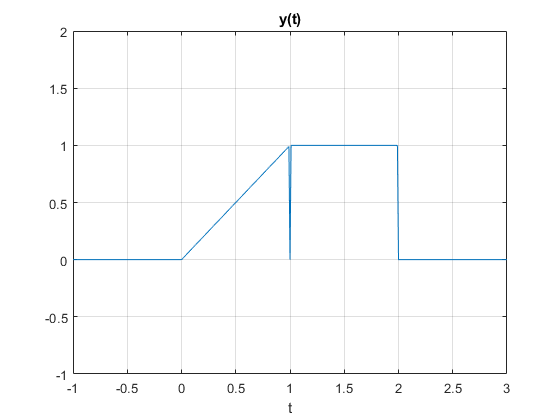

y = @(t) (t).*((t > 0) & (t<1)) + (1).*((1 < t)&(t < 2));
yV = (-1: 0.01: 4);
plot(yV, y(yV));
axis([-1 3 -1 2]);
title('y(t)');
xlabel('t');
grid on;

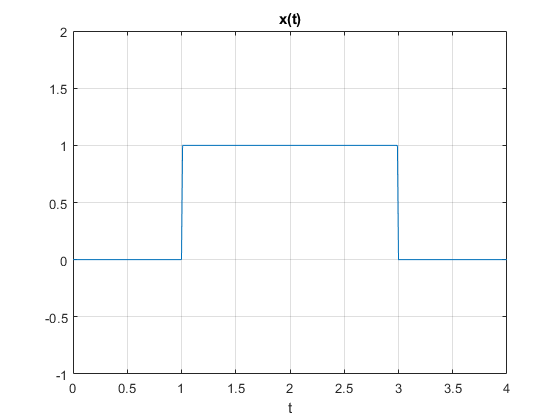

x = @(t) (1).*((t > 1) & (t<3));
xV = (-1: 0.01: 4);
plot(xV, x(xV));
axis([0 4 -1 2]);
title('x(t)');
xlabel('t');
grid on;

Para aplicar la convolución, usaríamos la definición y nuestra señal inversa movible  va a ser x(t):


$$g(x) = y(t)*x(t)= \int_{-\infty}^{\infty}y(\tau)x(t-\tau)\, d\tau$$


La convolución resultante sería:


$$\[ h(t) = 
\begin{cases}
\frac{1}{2}(-1+t)^2 & 1 \lt t \leq 2 \\
\frac{1}{2}(-3+2t) &2 \lt t \leq 3 \\ 
\frac{1}{2}(-6+6t-t^2) & 3 \lt t < 4 \\
5-t & 4 \leq t < 5 \\
0 & otro\ caso
\end{cases}
\]$$


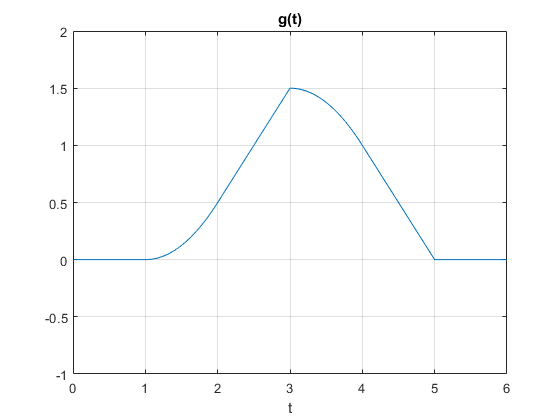

g = @(t) (1/2*(-1+t).^2).*((1 < t)&(t<=2)) + (1/2*(-3+2*t)).*((2 < t)&(t<=3))+ (1/2*(-6+6*t-t.^2)).*((3 < t)&(t < 4))+(5-t).*((4 <= t)&(t < 5));
gV = (-1:0.01: 6);
plot(gV, g(gV));
axis([0 6 -1 2]);
title('g(t)');
xlabel('t');
grid on;

Al comparar la señal generada de la numérica con su resultado analítico, podemos observar que concuerda correctamente debido a que son intervalos muy pequeños los que se estan uniendo con rectas.

Este es el ejemplo gráfico de cómo se generaría la convolución.

z =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [404 247 560 420]
       Units: 'pixels'

  Show all properties


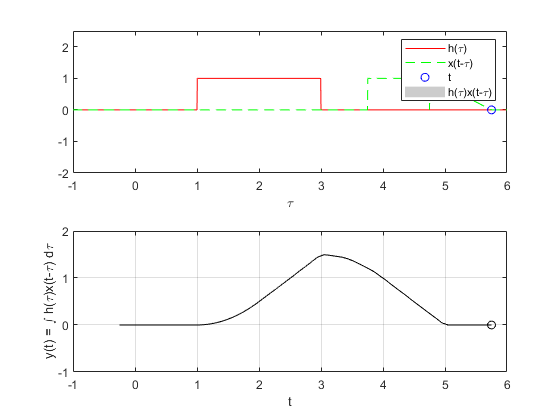

convconm(y,x, 'Problema3.gif');

function convconm(x,h, filename)
  z = figure (1) % Se crea una figura para hacer las gráficas
  dtau = 0.005; % Base de los rectangulos para realizar la integral 
  tau = -1:dtau:6; % Intervalo de visualización del resultado
  ti = 0; % Indice para el vector de resultados
  tvec = -.25:.1:5.75; % traslaciones de t, cuantas integrales se calulan  
  y = NaN*zeros(1, length (tvec)); % Resultados de acuerdo a cuantos t
  for t = tvec, % Cantidad de traslaciones
      ti = ti+1; % Indice para guardar el resultado (indice del tiempo)
      xh = x(t-tau).*h(tau); % resultado de la multiplicación 
      lxh = length(xh); % longitud del resultado
      y(ti) = sum(xh.*dtau); % Base por altura, aproximación de la integral
      subplot (2,1,1), % gráfica de 2 x 1 (primera)
      plot(tau, h(tau), 'r-', tau, x(t-tau), 'g--', t, 0, 'ob'); %graficas 
      axis ([tau(1) tau(end) -2.0 2.5]); % límites de los ejes
      patch([tau(1:end-1); tau(1:end-1); tau(2:end); tau(2:end)],...
      [zeros(1,lxh-1);xh(1:end-1);xh(2:end);zeros(1,lxh-1)],...
      [.8 .8 .8], 'edgecolor', 'none');
      xlabel('\tau'); % Texto del eje X
      legend('h(\tau)', 'x(t-\tau)','t','h(\tau)x(t-\tau)')% Caja de Texto  
      subplot (2, 1, 2)  % gráfica de 2 x 1 (segunda)
      plot (tvec, y, 'k', tvec (ti), y(ti), 'ok');
      xlabel ('t'); 
      ylabel ('y(t) = \int h(\tau)x(t-\tau) d\tau');
      axis ([tau(1) tau(end) -1.0 2.0]); % límites del eje
      grid; % malla
      drawnow; % efecto de movimiento continuo
      frame = getframe(z);
  
      im = frame2im(frame);
      [imind, cm] = rgb2ind(im, 256);
      
      if t == -.25
          imwrite(imind, cm, filename, 'gif', 'Loopcount', inf);
      else
          imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append');
      end
  
  end
  
  
  
  
  end


$$\[ h(t) = 
\begin{cases}
\frac{1}{2}(-1+t)^2 & 1 \lt t \leq 2 \\
\frac{1}{2}(31+2t) &2 \lt t \leq 3 \\ 
\frac{1}{2}(-t+6t-t^2) & 3 \lt t \lt 4 \\
5 - t & 4 \leq t \lt 5 \\
0 & otro\ caso
\end{cases}
\]$$
